clear;
clc;
close all

## LOADING DATASET

filename='Explant_ResponseGroup_Allprot_DEGs.xlsx';
% note: duplicated gene removed from Allprot dat.

tbl_exp_dat=readtable(filename,...
    'Sheet','DEG expression');

tbl_target_class=readtable(filename,...
    'Sheet','Target labels');

tbl_deg_pval=readtable(filename,...
    'Sheet','DEG pvals');

% expression data (to be normalized)
exp_dat_raw=table2array(tbl_exp_dat(:,2:end)); 
% gene names (input variable)
gene_name=tbl_exp_dat.GeneName;
% target lables (output labels)
class_label_dat = table2array(tbl_target_class);
% p-value (just for inform)
p_val=tbl_deg_pval.DEGs_Pval;

% drug response --> class labels
class_label = zeros(3,size(class_label_dat,2));
class_label(1,ismember(class_label_dat,{'NR'})) = 1;
class_label(2,ismember(class_label_dat,{'RD'})) = 1;
class_label(3,ismember(class_label_dat,{'PR'})) = 1;

## Expression data normalization

## predictor = expression data (normalized)

tmp_min = repmat(min(exp_dat_raw')',1,size(exp_dat_raw,2));
tmp_max = repmat(max(exp_dat_raw')',1,size(exp_dat_raw,2));
predictor = (exp_dat_raw -  tmp_min)./(tmp_max - tmp_min);

## RUN THE SIMULATION

No_cross_val = 50;
No_sample = size(predictor,2);


% random sampling for train (80%) and test (20%)
for ii = 1:No_cross_val
    rng(ii); % random number seed for reproducibility
    [train_sample_idx(ii,:),~,test_sample_idx(ii,:)] = dividerand(No_sample,0.8,0.0,0.2);
end

nd1 = No_cross_val;


parfor  idx1 =  1:nd1
    
    disp(idx1)
    
    % copy variables for par
    predictor_par = predictor;
    train_sample_idx_par = train_sample_idx;
    test_sample_idx_par = test_sample_idx;
    class_label_par = class_label;
    
    % random sampling for training an test
    train_idx=train_sample_idx_par(idx1,:);
    test_idx=test_sample_idx_par(idx1,:);
    
    % Train & Test data
    predictor_train = predictor_par(:,train_idx); % training input
    predictor_test = predictor_par(:,test_idx); % test input
    
    class_label_train = class_label_par(:,train_idx);
    class_label_true = class_label_par(:,test_idx);
    
    
    rng(idx1)
    net = patternnet(10);
    net.trainParam.showWindow = false;
    net.divideParam.trainRatio = 100/100;
    net.divideParam.valRatio = 0/100;
    net.divideParam.testRatio = 00/100;
    net = train(net,predictor_train,class_label_train,...
        'useGPU','no');
    tmp_class_label_prd_par = sim(net,predictor_test);
    class_label_pred_par(:,:,idx1) = tmp_class_label_prd_par;
    
    
    
    [~,class_label_pred_index(:,idx1)] = max(tmp_class_label_prd_par);
    [~,class_label_true_index(:,idx1)] = max(class_label_true);
    
    
end

     1

     2

     3

     4

     5

     6

     7

     8

    11

    10

    14

    20

    19

    23

    22

    13

    12

    17

    16

    26

    29

    28

    32

    31

     9

    33

    15

    18

    21

    25

    24

    27

    30

    41

    39

    37

    35

    36

    38

    34

    44

    42

    40

    43

    50

    49

    46

    45

    48

    47




% [m,order] = confusionmat(class_label_true_index(:),class_label_pred_index(:));
% score= sum(diag(m)/length(class_label_pred_index(:)))

## post-processing

parfor idx1 = 1:nd1
            
    [cmat,~] = confusionmat(class_label_true_index(:,idx1),class_label_pred_index(:,idx1));
    score_mat(idx1)= sum(diag(cmat)/length(class_label_true_index(:,idx1)));
    
end

avg_prediction_acc = mean(score_mat);

## Plot a distribution of curve for prediction accuracy

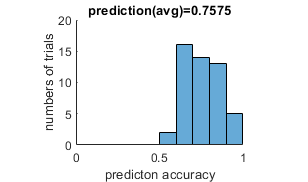

figure('Position',[680   796   308   182])

pbaspect([4 3 1]/4)
edges = [0:0.1:1];
histogram(score_mat,edges)
title(strcat('prediction(avg)=',num2str(mean(score_mat))))
xlabel('predicton accuracy'),ylabel('numbers of trials')
pbaspect([4 3 1]/4)
box off

## confusion matrix

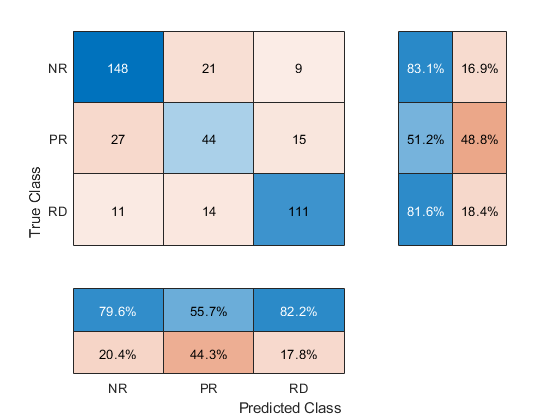

[cfm,order] = confusionmat(class_label_true_index(:),class_label_pred_index(:));

tmp_class_label_true_index = cell(size(class_label_true_index(:)));
tmp_class_label_true_index(ismember(class_label_true_index(:),1)) = {'NR'};
tmp_class_label_true_index(ismember(class_label_true_index(:),2)) = {'RD'};
tmp_class_label_true_index(ismember(class_label_true_index(:),3)) = {'PR'};

tmp_class_label_pred_index = cell(size(class_label_pred_index(:)));
tmp_class_label_pred_index(ismember(class_label_pred_index(:),1)) = {'NR'};
tmp_class_label_pred_index(ismember(class_label_pred_index(:),2)) = {'RD'};
tmp_class_label_pred_index(ismember(class_label_pred_index(:),3)) = {'PR'};


figure
cm = confusionchart(tmp_class_label_true_index(:),tmp_class_label_pred_index(:), ...
    'ColumnSummary','column-normalized', ... % 'column-normalized' % 'total-normalized'
    'RowSummary','row-normalized');  % 'row-normalized'

## ROC curves

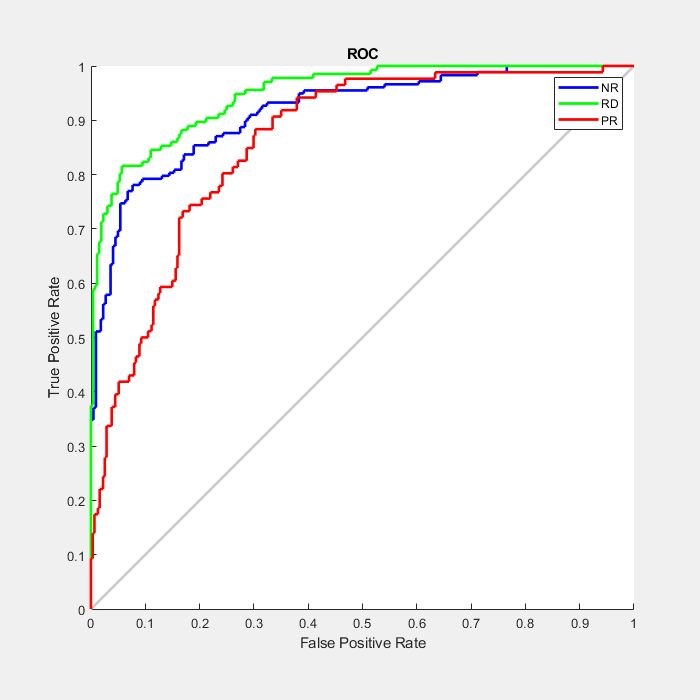

class_label_true_binary = zeros(3,size(class_label_true_index(:),1));
class_label_true_binary(1,ismember(class_label_true_index(:),1)) = 1;
class_label_true_binary(2,ismember(class_label_true_index(:),2)) = 1;
class_label_true_binary(3,ismember(class_label_true_index(:),3)) = 1;

class_label_pred_probability = [];
for ii = 1:size(class_label_pred_par,3)

    class_label_pred_probability = [class_label_pred_probability class_label_pred_par(:,:,ii)];

end

[tpr,fpr,thresholds] = roc(class_label_true_binary,class_label_pred_probability);
figure('position',[610   599   249   291])
plotroc(class_label_true_binary,class_label_pred_probability)
axesUserData = get(gca, 'userdata'); 
legend(axesUserData.lines, 'NR', 'RD','PR');




% class_label(1,ismember(response_dat_0,{'RD'})) = 1;
% class_label(2,ismember(response_dat_0,{'NR'})) = 1;
% class_label(3,ismember(response_dat_0,{'PR'})) = 1;